close all;
clear;

g = 9.8;
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;

Defining system matrices after substituting the mass and cable lengths

A = [0 1 0 0 0 0;
    0 0 ((-g*m1)/M) 0 ((-g*m2)/M) 0;
    0 0 0 1 0 0;
    0 0 ((-g*(M+m1))/(M*l1)) 0 -((g*m2)/(M*l1)) 0;
    0 0 0 0 0 1;
    0 0 ((-g*m1)/(M*l2)) 0 ((-g*(M+m2))/(M*l2)) 0 ];

B = [0;
    (1/M);
    0;
    (1/(M*l1));
    0;
    (1/(M*l2))];

Defining Controllability Matrix

AB = A*B;
A2B = (A^2)*B;
A3B = (A^3)*B;
A4B = (A^4)*B;
A5B = (A^5)*B;

Ac = [B AB A2B A3B A4B A5B] ;
disp("Controllability Matrix is: ");

Controllability Matrix is: 


disp(Ac);

   1.0e-03 *

         0    1.0000         0   -0.1470         0    0.1417
    1.0000         0   -0.1470         0    0.1417         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1127         0    0.1246
    0.1000         0   -0.1127         0    0.1246         0



det_Ac = det(Ac);
rank_Ac = rank(Ac);
disp("Determinant of Ac after substituting values is: ");

Determinant of Ac after substituting values is: 


disp(det_Ac);

  -1.3841e-24



disp("Rank of Ac after substituting values is: ");

Rank of Ac after substituting values is: 


disp(rank_Ac);

     6



C = eye(6);
D = [0; 0; 0; 0; 0; 0];

Assume initial Q and R values

Q = eye(6);
R = 0.01;
[K,S,P] = lqr(A,B,Q,R);
disp(P);

  -0.0006 + 0.7282i
  -0.0006 - 0.7282i
  -0.0010 + 1.0425i
  -0.0010 - 1.0425i
  -0.0646 + 0.0645i
  -0.0646 - 0.0645i



disp(K);

   10.0000  155.1171  -12.6608 -224.9890   -6.2965 -112.9358



K1 = K(1);
At = A - B*K;

%Defining system without a controller
sys1 = ss(A,B,C,D);
%Defining system after adding LQR Controller
sys2 = ss(A-B*K,B,C,D);

e = eig((A-B*K));
disp(e);

  -0.0646 + 0.0645i
  -0.0646 - 0.0645i
  -0.0010 + 1.0425i
  -0.0010 - 1.0425i
  -0.0006 + 0.7282i
  -0.0006 - 0.7282i



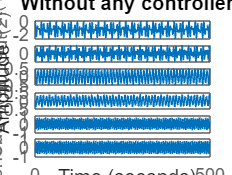

x_0 = [0;0;0.5;0;0.6;0];
initial(sys1,x_0);
xlim([0 500]);
title("Without any controller")

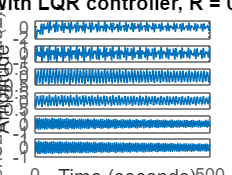


initial(sys2,x_0);
xlim([0 500]);
title("With LQR controller, R = 0.01")

As can be seen, the system is not yet stable. And hence value of Q is increased and value of R is decreased.

Q defines the performance and R defines the effort of the system.

%Changing Q and R values
Q = 10*eye(6);
R = 0.001;
[K,S,P] = lqr(A,B,Q,R);

%Defining system after adding LQR Controller
sys3 = ss(A-B*K,B,C,D);

e = eig((A-B*K));
disp(e);

  -0.2067 + 0.2024i
  -0.2067 - 0.2024i
  -0.0103 + 1.0416i
  -0.0103 - 1.0416i
  -0.0061 + 0.7273i
  -0.0061 - 0.7273i



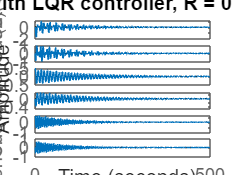

x_0 = [0;0;0.5;0;0.6;0];
initial(sys3,x_0);
xlim([0 500]);
title("With LQR controller, R = 0.001")

%Changing Q and R values
Q = 100*eye(6);
R = 0.0001;
[K,S,P] = lqr(A,B,Q,R);
K1 = K(1);
At = A - B*K;

%Defining system after adding LQR Controller
sys4 = ss(A-B*K,B,C,D);

e = eig((A-B*K));
disp(e);

  -0.8205 + 0.5306i
  -0.8205 - 0.5306i
  -0.0505 + 1.0041i
  -0.0505 - 1.0041i
  -0.0199 + 0.7051i
  -0.0199 - 0.7051i



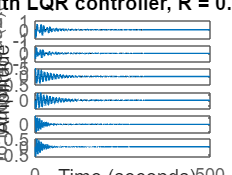

x_0 = [0;0;0.5;0;0.6;0];

initial(sys4,x_0);
xlim([0 500]);
title("With LQR controller, R = 0.0001")

As value of Q increases the performance increases and as the value of R decreases the system gets stable fast.